# **SS - lab S3 - Zeic Beniamin**

#### Exercise 1

In order to represent the given signals in Matlab, we firstly define the unit step function, then we find the mathematical expression of each signal, and then we plot it using Matlab.

% The unit step signal
u0=@(t)(t>=0);

% linspace for the plotting interval
t = linspace(-1.5,3, 1000);
% Signal amplitutde
A = 2;
% Signal period
T = 1;

The first signal has the equation:


$$x_1 \left(t\right)=-Au_0 \left(t\right)\;$$


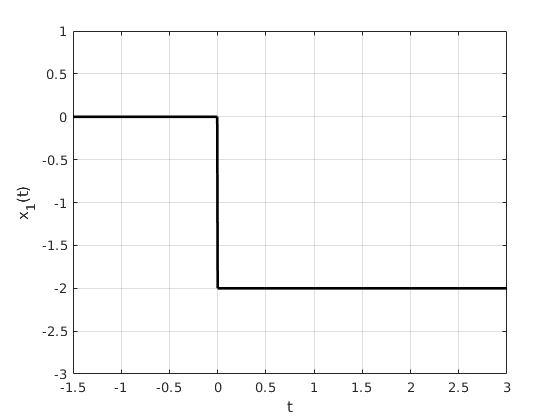

% Equation of the signalrr
x1=@(t)(-A*u0(t));
plot(t, x1(t), 'LineWidth', 2, 'Color', [0 0 0]);
% Format the plot appropriately
grid
axis([min(t), max(t), min(x1(t))-1, max(x1(t))+1]);
xlabel('t')
ylabel('x_1(t)')

The second signal:


$$x_2 \left(t\right)=-Au_0 \left(t-T\right)$$


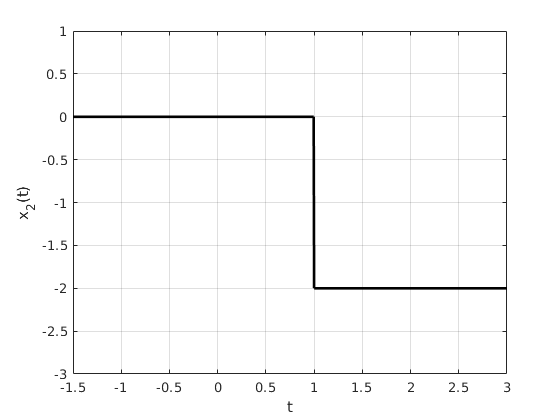

% Equation
x2=@(t)(-A*u0(t-T));

plot(t, x2(t), 'LineWidth', 2, 'Color', [0 0 0]);
% Format the plot appropriately
grid
axis([min(t), max(t), min(x2(t))-1, max(x2(t))+1]);
xlabel('t')
ylabel('x_2(t)')

The third signal:


$$x_3 \left(t\right)=-Au_0 \left(t+T\right)$$


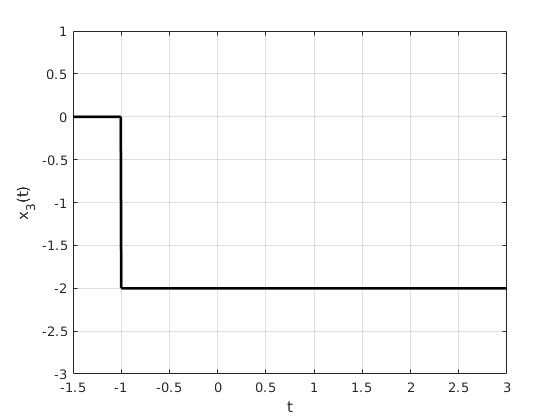

% Equation
x3=@(t)(-A*u0(t+T));

plot(t, x3(t), 'LineWidth', 2, 'Color', [0 0 0]);
% Format the plot appropriately
grid
axis([min(t), max(t), min(x3(t))-1, max(x3(t))+1]);
xlabel('t')
ylabel('x_3(t)')

The fourth signal:


$$x_4 \left(t\right)={\textrm{Au}}_0 \left(-t\right)$$


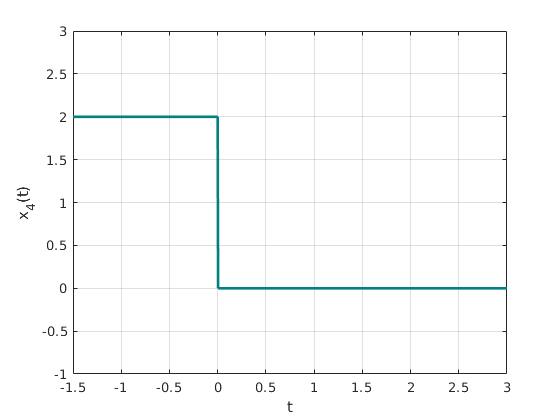

% Equation
x4=@(t)(A*u0(-t));

plot(t, x4(t), 'LineWidth', 2, 'Color', [0 0.5 0.5]);
% Format the plot appropriately
grid
axis([min(t), max(t), min(x4(t))-1, max(x4(t))+1]);
xlabel('t')
ylabel('x_4(t)')

The fifth signal:


$$x_5 \left(t\right)=Au_0 \left(-t+T\right)$$


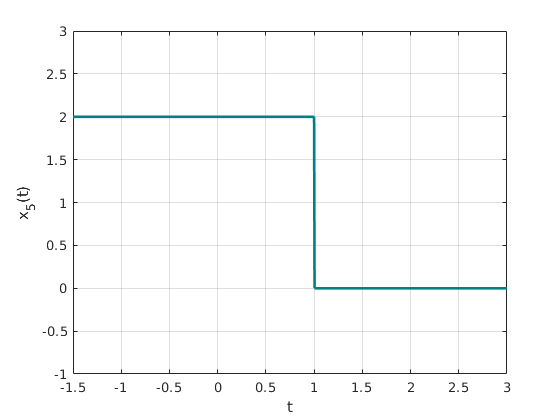

% Equation
x5=@(t)(A*u0(-t+T));

plot(t, x5(t), 'LineWidth', 2, 'Color', [0 0.5 0.5]);
% Format the plot appropriately
grid
axis([min(t), max(t), min(x5(t))-1, max(x5(t))+1]);
xlabel('t')
ylabel('x_5(t)')

The sixth signal:


$$x_6 \left(t\right)={\textrm{Au}}_0 \left(-t-T\right)$$


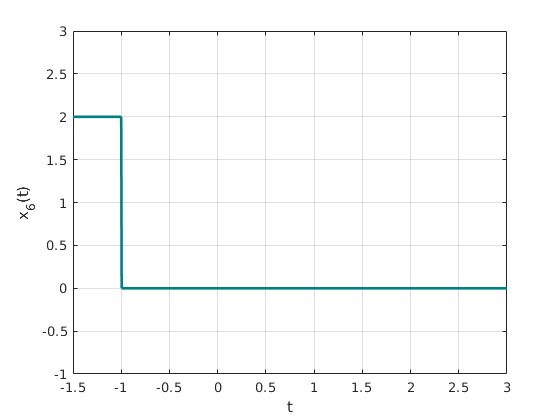

% Equation
x6=@(t)(A*u0(-t-T));

plot(t, x6(t), 'LineWidth', 2, 'Color', [0 0.5 0.5]);
% Format the plot appropriately
grid
axis([min(t), max(t), min(x6(t))-1, max(x6(t))+1]);
xlabel('t')
ylabel('x_6(t)')

The seventh signal:


$$x_7 \left(t\right)={\textrm{Au}}_0 \left(t\right)-A$$


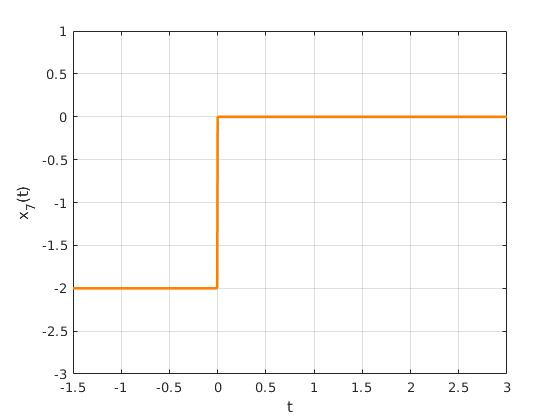

% Equation
x7=@(t)(A*u0(t)-A);

plot(t, x7(t), 'LineWidth', 2, 'Color', [1 0.5 0]);
% Format the plot appropriately
grid
axis([min(t), max(t), min(x7(t))-1, max(x7(t))+1]);
xlabel('t')
ylabel('x_7(t)')

The eighth signal:


$$x_8 \left(t\right)={\textrm{Au}}_0 \left(t-T\right)-A$$


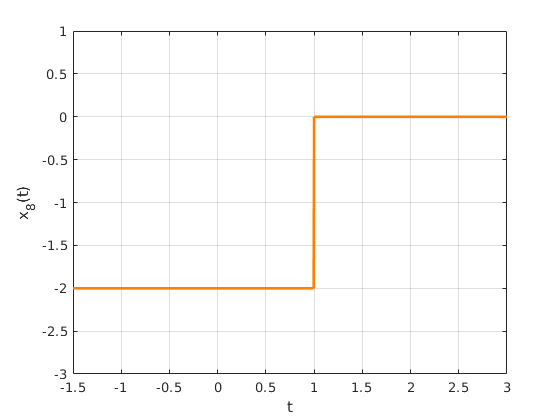

% Equation
x8=@(t)(A*u0(t-T)-A);

plot(t, x8(t), 'LineWidth', 2, 'Color', [1 0.5 0]);
% Format the plot appropriately
grid
axis([min(t), max(t), min(x8(t))-1, max(x8(t))+1]);
xlabel('t')
ylabel('x_8(t)')

The ninth signal:


$$x_9 \left(t\right)={\textrm{Au}}_0 \left(t+T\right)-A$$


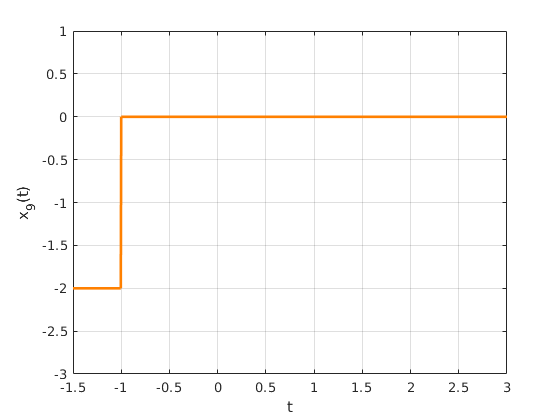

% Equation
x9=@(t)(A*u0(t+T)-A);

plot(t, x9(t), 'LineWidth', 2, 'Color', [1 0.5 0]);
% Format the plot appropriately
grid
axis([min(t), max(t), min(x9(t))-1, max(x9(t))+1]);
xlabel('t')
ylabel('x_9(t)')

#### Exercise 2

Evaluate the expressions:

**A.**


$$\int_{-4}^7 \sin \left(\pi t\right)\delta \left(t-1\right)\textrm{dt}=\sin \left(\pi \right)$$


Since $\delta \left(t-1\right)$ is non-zero only for $t=1$, we can rewrite the above equation as:


$$\int_{-4}^7 \sin \left(\pi \right)\delta \left(t-1\right)\textrm{dt}=\sin \left(\pi \right)\int_{-4}^7 \delta \left(t-1\right)\textrm{dt}$$


Since the interval $\left(-4,7\right)$contains the point $t=1$, the integral will evaluate to one.

Thus, the final result is $\sin \left(\pi \right)$.

**B. **


$$\int_0^2 \sin \left(\pi t\right)\delta \left(t-3\right)\textrm{dt}=0$$


Since $t=3\not\in \left(0,2\right)$ we can see that the integral will evaluate to zero.

**C.**


$$e^{-t} \cos \left(10t\right)\delta \left(t\right)=\delta \left(t\right)$$


By applying the sampling property, we get:


$$e^{-t} \mathrm{cos}\left(10t\right)\delta \left(t\right)=e^0 \mathrm{cos}\left(0\right)\delta \left(t\right)$$


We know the value of the exponential and of the cosine for $t=0$ is $e^0 \mathrm{cos}\left(0\right)=1$. Thus, we are left only with $\delta \left(t\right)$.

**D.**


$$\mathrm{sin}\left(2\pi t\right)\sum_{k=0}^{\infty } \delta \left(t-k\right),k\in Z$$


We have a sum of delta functions multiplied by the sine function. By applying the distributivity property, we obtain a sum of sines multiplied by delta functions at time moments $k\in Z,k>0$.


$$\mathrm{sin}\left(2\pi t\right)\sum_{k=0}^{\infty } \delta \left(t-k\right)=\sum_{k=0}^{\infty } \mathrm{sin}\left(2\pi k\right)\delta \left(0\right)$$


#### Exercise 3 - part 1

For the signal presented in the figure, find an analytical expression based on the unit step function.

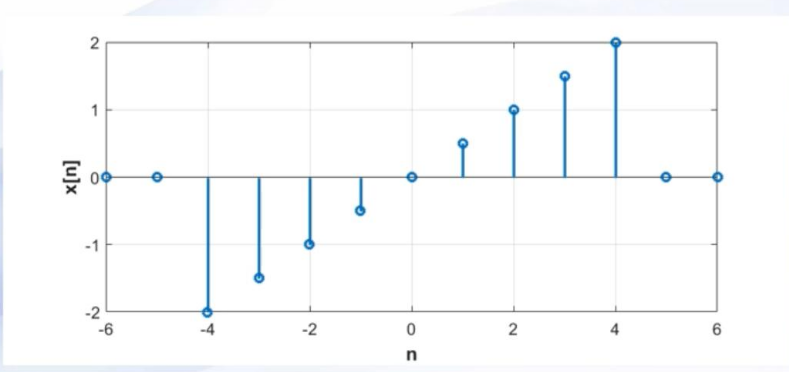

The given signal is the $f\left(t\right)=\frac{1}{2}t,t\in \left\lbrack -4,4\right\rbrack$ function, sampled at integer values of x.

The analytical expression of the signal is:


$$x\left(t\right)=\left(u_0 \left(t+5\right)-u_0 \left(t-4\right)\right)\frac{1}{2}t$$


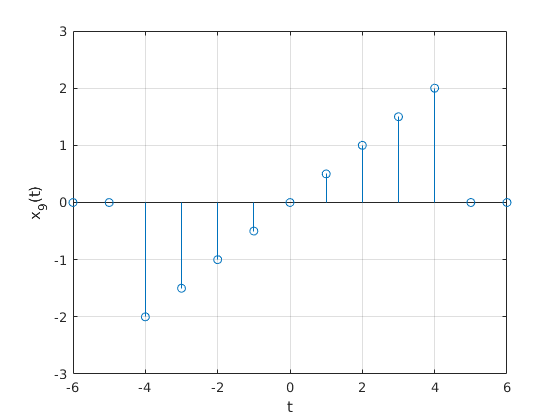

clear all;
% Declare the unit step function as an anonymous function
u0 = @(t)(t>0);
% Generate the linear space
t = linspace(-6, 6, 13);
% Define the discrete function that gives us the graph above
func=@(x)((u0(x+5)-u0(x-4)).*(1/2*x));
stem(t, func(t)); grid
axis([-6, 6, min(func(t))-1, max(func(t))+1]);
xlabel('t')
ylabel('x_9(t)')

#### Exercise 3 - part 2

Represent the following signals in Matlab

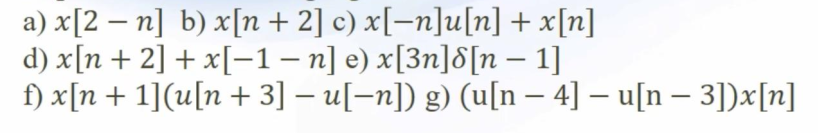

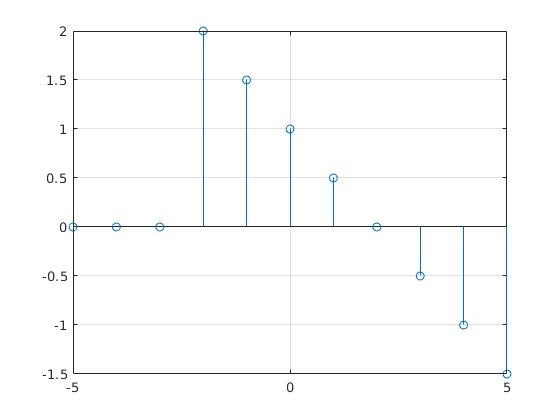

n = -5:5;
stem(n, func(2-n));grid

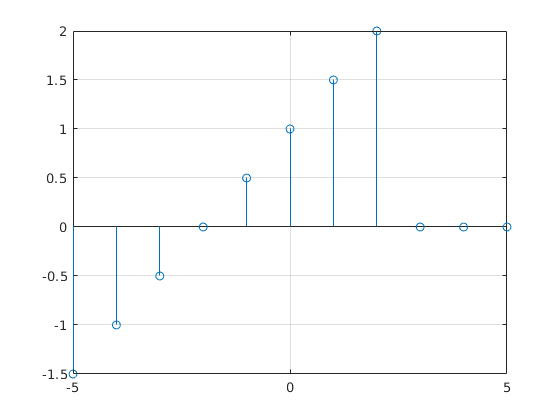

stem(n, func(n+2));grid

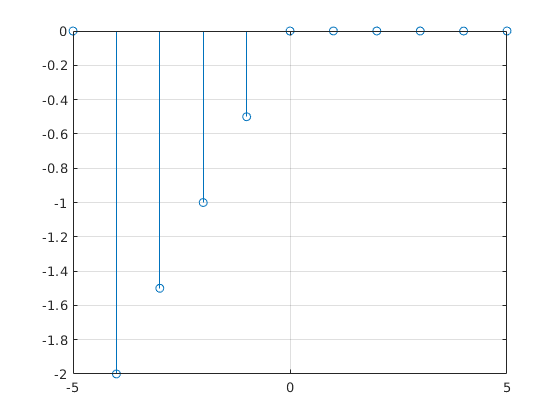

stem(n, func(-n).*u0(n)+func(n));grid

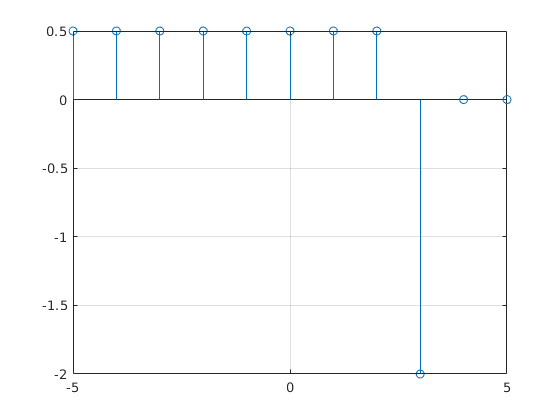

stem(n, func(n+2)+func(-1-n));grid

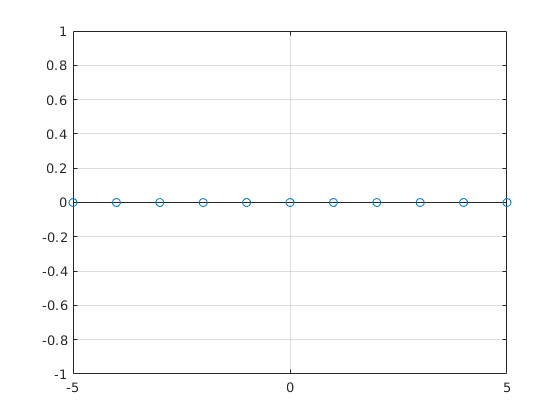

% Model delta as u0(n) - u0(n-1)
stem(n, func(3*n).*(u0(n-1)-u0(n-2)));grid

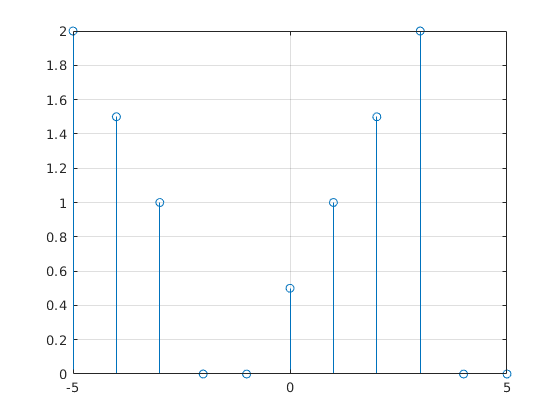

stem(n, func(n+1).*(u0(n+3)-u0(-n)));grid

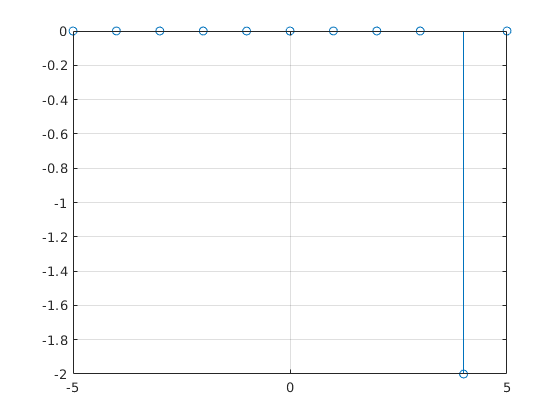

stem(n, func(n).*(u0(n-4)-u0(n-3)));grid